close all
clear
clc

# ***Linear Regression on Abalone Dataset***

## **Information on the dataset**

**Title** : Abalone dataset

**Source **: UCI Machine Learning repository ([https://archive.ics.uci.edu/ml/datasets/Abalone](https://archive.ics.uci.edu/ml/datasets/Abalone))

**Relevant Information:**

           Abalone are shellfish, a genus of gastropods which can be found all over the world.  The age of abalone is determined by cutting the shell through the cone, staining it, and counting the number of rings through a microscope -- a boring and time-consuming task. Other measurements, which are easier to obtain, are used to predict the age.  Further information, such as weather patterns and location (hence food availability) may be required to solve the problem.

            **This is a simple linear regression model with rational features used to predict the age (Number of rings)  of abalone given certain external features. Eventhough the responses are categorical, a linear regression model is used. As the age can be thought of as a continuos entity.**

### **Dataset features**

- **Number of instances **: 4177

- **Number of attributes** : 8

- **Missing Attribute values** : None

### **Attribute information**

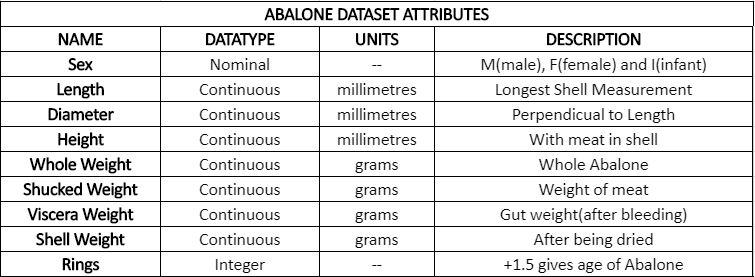

## **Loading the data**

data = readtable("abalone.data", "FileType","text");
varname = {'Sex', 'Length', 'Diameter', 'Height', 'WholeWeight', 'ShuckedWeight', 'VisceraWeight', 'ShellWeight', 'Rings'};
data.Properties.VariableNames = varname;

## **Plots**

Plots that describe the relation of number of rings with remaining features

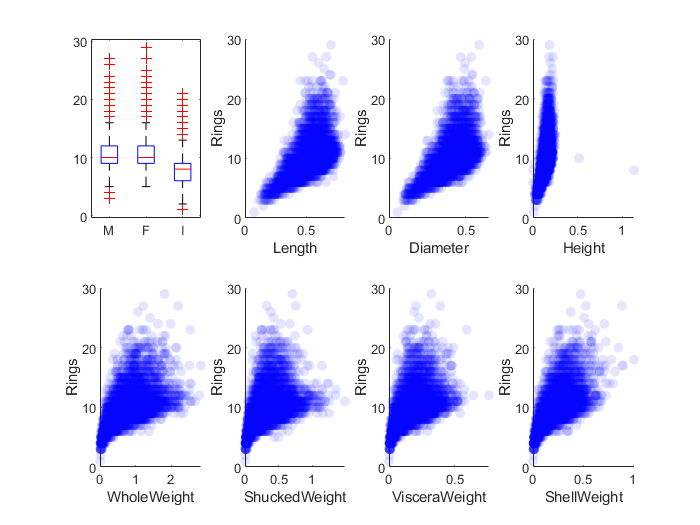

subplot(2,4,1)
boxplot(data.Rings, data.Sex);
for i = 2:8
    subplot(2,4,i)
    scatter(table2array(data(:,i)), data.Rings, 'filled','bo', 'MarkerFaceAlpha', 0.1)
    xlabel(varname(i));
    ylabel('Rings');
end

            From the above plots we can see that Number of Rings seems to be proportional to square of Length, Diameter and Height while it seems to be proportional to square root of all kinds of weights. On the other hand looking at the boxplot eventhough the median Number of Rings in infant Abalones is less than Male or Female Abalones there are a lot of outlier values. Hence the attribute 'Sex' can affect the model adversely. Therefore drop the 'Sex' attribute.

## Converting data to usable form

**Converting table to matrices by dropping 'Sex' attribute**

X = table2array(data(:,2:8));
y = data.Rings;
[m, n] = size(X);

### Feature Engineering

**Adding new features: quadratic and square root**

f = 1 + 2*n + (n*(n+1))/2;
Xnew = zeros(m, f);
Xnew(:,1) = ones(m,1);
Xnew(:, 2:8) = X;
cur = 9;
for i = 1:n
    for j = i:n
        Xnew(:, cur) = X(:,i).*X(:,j);
        cur = cur+1;
    end
end
Xnew(:, cur:end) = sqrt(X);
X = Xnew;
[m, n] = size(X);

**Dividing the dataset into training (60%), cross validation (20%) and test (20%) sets**

[Xtrain, ytrain, Xval, yval, Xtest, ytest] = dataDivide(X, y, 60, 20);

## **Linear Regression with Regularization**

### **Model Selection, Training and Evaluation**

#### Selecting the optimal value of alpha, lambda, niter using a smaller validation set

Theta0 = zeros(n, 1);
[alpha, lambda, niter] = selectModel(Xval, yval, Theta0);
%Using the above function the following values were obtained
%alpha = 0.1; lambda = 0.3; niter = 2500;
fprintf("alpha = %f\tlambda = %f\tniter = %f", alpha, lambda, niter);

alpha = 0.100000	lambda = 0.300000	niter = 2500.000000

#### Training on the training set

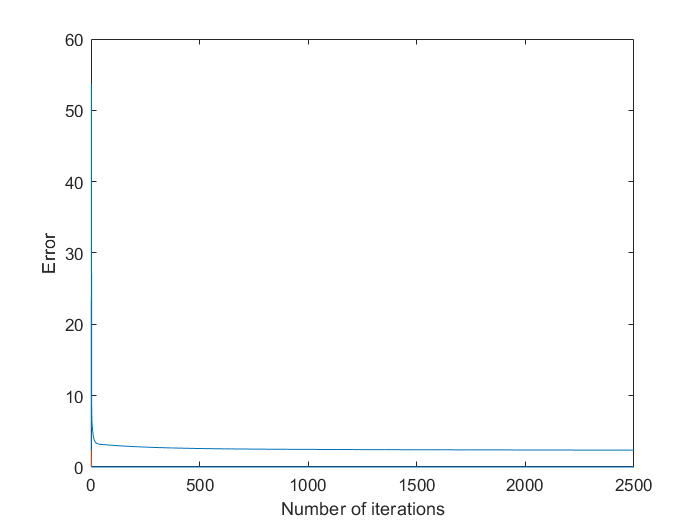


[Theta, J] = gradientDescent(Xtrain, ytrain, Theta0, alpha, lambda, niter);

close all hidden
plot(J);
xlabel("Number of iterations");
ylabel("Error");

fprintf("Error = %f", J(niter));

Error = 2.358854

#### Plot of predicted responses vs actual responses for Training set and Test set

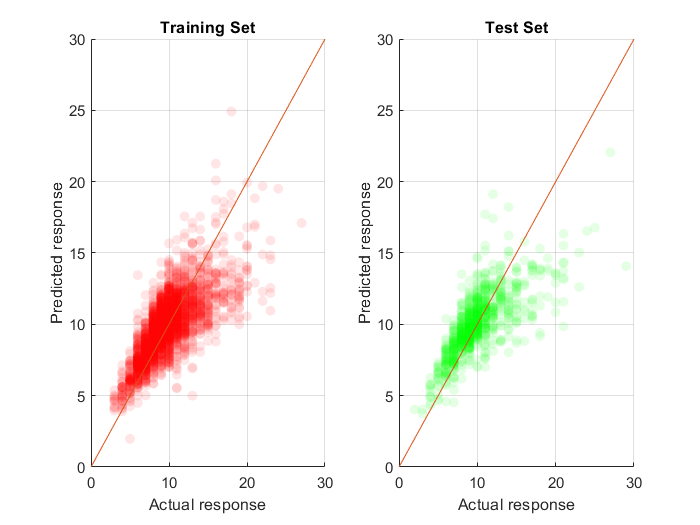

subplot(1,2,1)
scatter(ytrain, Xtrain*Theta, 'filled', 'ro', 'MarkerFaceAlpha', 0.1)
hold on
plot(0:30, 0:30)
hold off
title("Training Set")
xlabel('Actual response')
ylabel('Predicted response')
grid on

subplot(1,2,2)
scatter(ytest, Xtest*Theta, 'filled', 'go', 'MarkerFaceAlpha', 0.1)
hold on
plot(0:30, 0:30)
hold off
title("Test Set")
xlabel('Actual response')
ylabel('Predicted response')
grid on

#### Mean Squared errors in training set and test set

MSE1 = (1/(2*(length(ytrain))))*((Xtrain*Theta - ytrain)'*(Xtrain*Theta - ytrain));
MSE2 = (1/(2*(length(ytest))))*((Xtest*Theta - ytest)'*(Xtest*Theta - ytest));

fprintf("Root Mean Squared Error in Training set = %f\nRoot Mean Squared Error in Training set = %f", sqrt(MSE1), sqrt(MSE2));

Root Mean Squared Error in Training set = 1.532609
Root Mean Squared Error in Training set = 1.687090

## **Conclusions**

            As the number of rings is an integer value the round off of the predicted value can be vaguely considered as the number of rings in the Abalone. The average root mean squared error for the model is 1.5. The given features are highly related to each other as we can see from the plots below. Diameter increase linearly with length while Weights increase quadratically with length. Thus effectively there is very less features to work on. More kinds of features (e.g, food availability) may be required to predict the age with a higher amount of accuaracy.

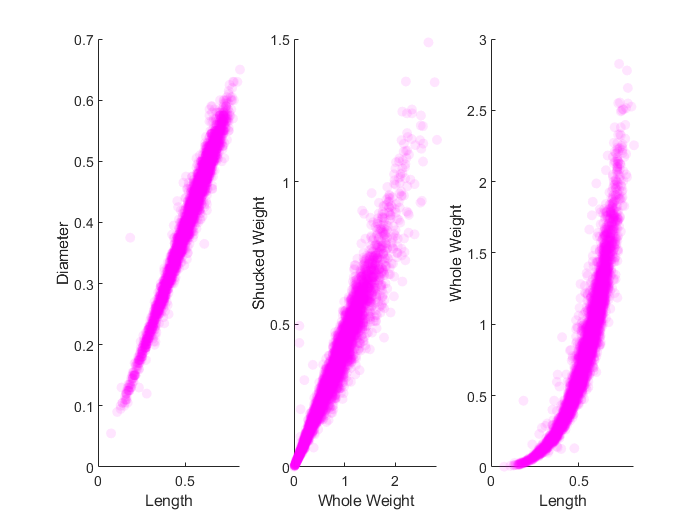

close all hidden
subplot(1,3,1)
scatter(data.Length, data.Diameter, 'mo', 'filled', 'MarkerFaceAlpha', 0.1)
xlabel('Length')
ylabel('Diameter')
subplot(1,3,2)
scatter(data.WholeWeight, data.ShuckedWeight, 'mo', 'filled', 'MarkerFaceAlpha', 0.1)
xlabel('Whole Weight')
ylabel('Shucked Weight')
subplot(1,3,3)
scatter(data.Length, data.WholeWeight, 'mo', 'filled', 'MarkerFaceAlpha', 0.1)
xlabel('Length')
ylabel('Whole Weight')